# Behavioral analysis of flight room training on 1/20/2024

## Experiment infomation

Recording data: 1/20/2024

cdp data: 240120_cdp_pretrain

Number of sessions: 1

Reward flavior: banana

%% Experiment info
n_session = 1;
n_feeder = 4;
reward_list = {"banana"};
n_flavior = length(reward_list);
reward_session = [1,1,1,1]; % row = session, col = flavor. number is corresponding to the flavor in reward_flavor. 0 = no flavor is allocated.

## Data structure

cortex: reward and TTL signals

cdp: bat position and acceleration

reward: feeder landing

camera: camera recordings

analysis: directory to save all outputs of analysis

Serial_numbers.txt: serial number of tags

%% Directory
data_dir = pwd;
fprintf('Data directory is %s',pwd)

Data directory is Z:\users\Tatsumi\data\MultiReward\training\groupC\240120_1

% cortex
cortex_dir  =   dir(fullfile(data_dir,'cortex','*c3d'));
cortex_file =   fullfile(cortex_dir.folder,cortex_dir.name);
% reward
reward_dir  =   dir(fullfile(data_dir,'reward','*.mat'));
% cdp
cdp_dir     =   dir(fullfile(data_dir,'cdp','*cdp*.txt'));
cdp_file    =   fullfile(cdp_dir.folder,cdp_dir.name);
% serial number
serial_dir  =   dir(fullfile(data_dir,'*Serial_numbers*'));
serial_file =   fullfile(serial_dir.folder,serial_dir.name);
% analysis
res_dir_path     =   fullfile(data_dir,'analysis');
if isempty(dir(res_dir_path))
    mkdir(res_dir_path)
end
% Figure
fig_dir_path    =   fullfile(res_dir_path,'figure');
if isempty(dir(fig_dir_path))
    mkdir(fig_dir_path)
end

## Preprocessing

### Preprocess raw tag data

Extract the tag data from the raw cdp data by the *ExtractCdp* function. *sync_data(:,8)* is the timestamps interpolated based on the pseudo-Fibonacci TTLs. In this time vector, t=0 is the timing of the 1st pulse of the pseudo-Fibonacci TTLs. Make sure that this time vector will be shifted for 1.05 sec to set t=0 as the 1st pulse of the 3-sec TTLs.

% Preprocess raw cdp data
cdp_extracted   =   dir(fullfile(res_dir_path,'extracted*cdp*')); % raw cdp data
serial_number   =   load(serial_file); serial_number   =   serial_number'; % serial number of tags
if isempty(cdp_extracted)
    cd(cdp_dir.folder)
    ExtractCdp_AF_TY_v2('cdp',res_dir_path,'Include',serial_number) % Extract cdp data keeping the tag order
    cd(data_dir)
    % Load data
    cdp_extracted   =   dir(fullfile(res_dir_path,'extracted*cdp*'));
    load(fullfile(cdp_extracted.folder,cdp_extracted.name))
elseif length(cdp_extracted) == 1
    disp('Extracted data are found in the directory.')
    load(fullfile(cdp_extracted.folder,cdp_extracted.name))
else
    error('Multiple files with the specified name were found. Check the file name.')
end

Extracted data are found in the directory.


Output file is *extracted_YYMMDD_cdp_*.mat* under the "analysis" directory.

### Extract behavior data

The *Process_extracted_cdp* function extract behavioral features from the preprocessed data. The output is *Extracted_Behavior_YYMMDD.mat* under the "Ext_Behavior_YYMMDD_HHMM.mat" directory.

The variable *t* in the output file is the time vector for global time. The global time is set so that t=0 is the timing of the 1st 3-sec TTLs.

% Extract behaviors
beh_dir         =   dir(fullfile(res_dir_path,'Ext_Behavior*','Extracted_Behavior*'));
if isempty(beh_dir)
    cd(res_dir_path)
    Process_extracted_cdp_TY_v0(res_dir_path) % Extract behavioral features
    cd(data_dir)
    % Load data
    beh_dir         =   dir(fullfile(res_dir_path,'Ext_Behavior*','Extracted_Behavior*'));
    load(fullfile(beh_dir.folder,beh_dir.name))
elseif length(cdp_extracted) == 1
    disp('Behavior data are found in the directory.')
    load(fullfile(beh_dir.folder,beh_dir.name))
    disp('Behavior data are loaded.')
else
    error('Multiple files were contained in the directory. Check the file name.')
end

Behavior data are found in the directory.


Behavior data are loaded.


### Extract feeder data

The information related to reward provision is stored in the MATLAB files in the reward directory. These files contain the timings of reward provision, the identity of the bat who landed on feeders, the identity of feeders, etc.

#### Extracting sync signals

Extract the sync and reward information from the c3d file and save them into a MATLAB file.

% Extract synchronization and reward signals from c3d file
analog_dir = dir(fullfile(cortex_dir.folder,'analog_signal.mat'));
if isempty(analog_dir)
    [~,~,AnalogSignals,AnalogFrameRate,~,~,~] = readC3D_analog(cortex_file); % read C3D data. Column 1 = reward, Column 2 = TTL, Column 3 = CDP server
elseif length(analog_dir)==1
    disp('Analog signal data are found.')
    load(fullfile(res_dir_path,'analog_signal.mat'),'AnalogSignals','AnalogFrameRate')
else
    error('Multiple files were contained in the directory. Check the file name.')
end

Analog signal data are found.


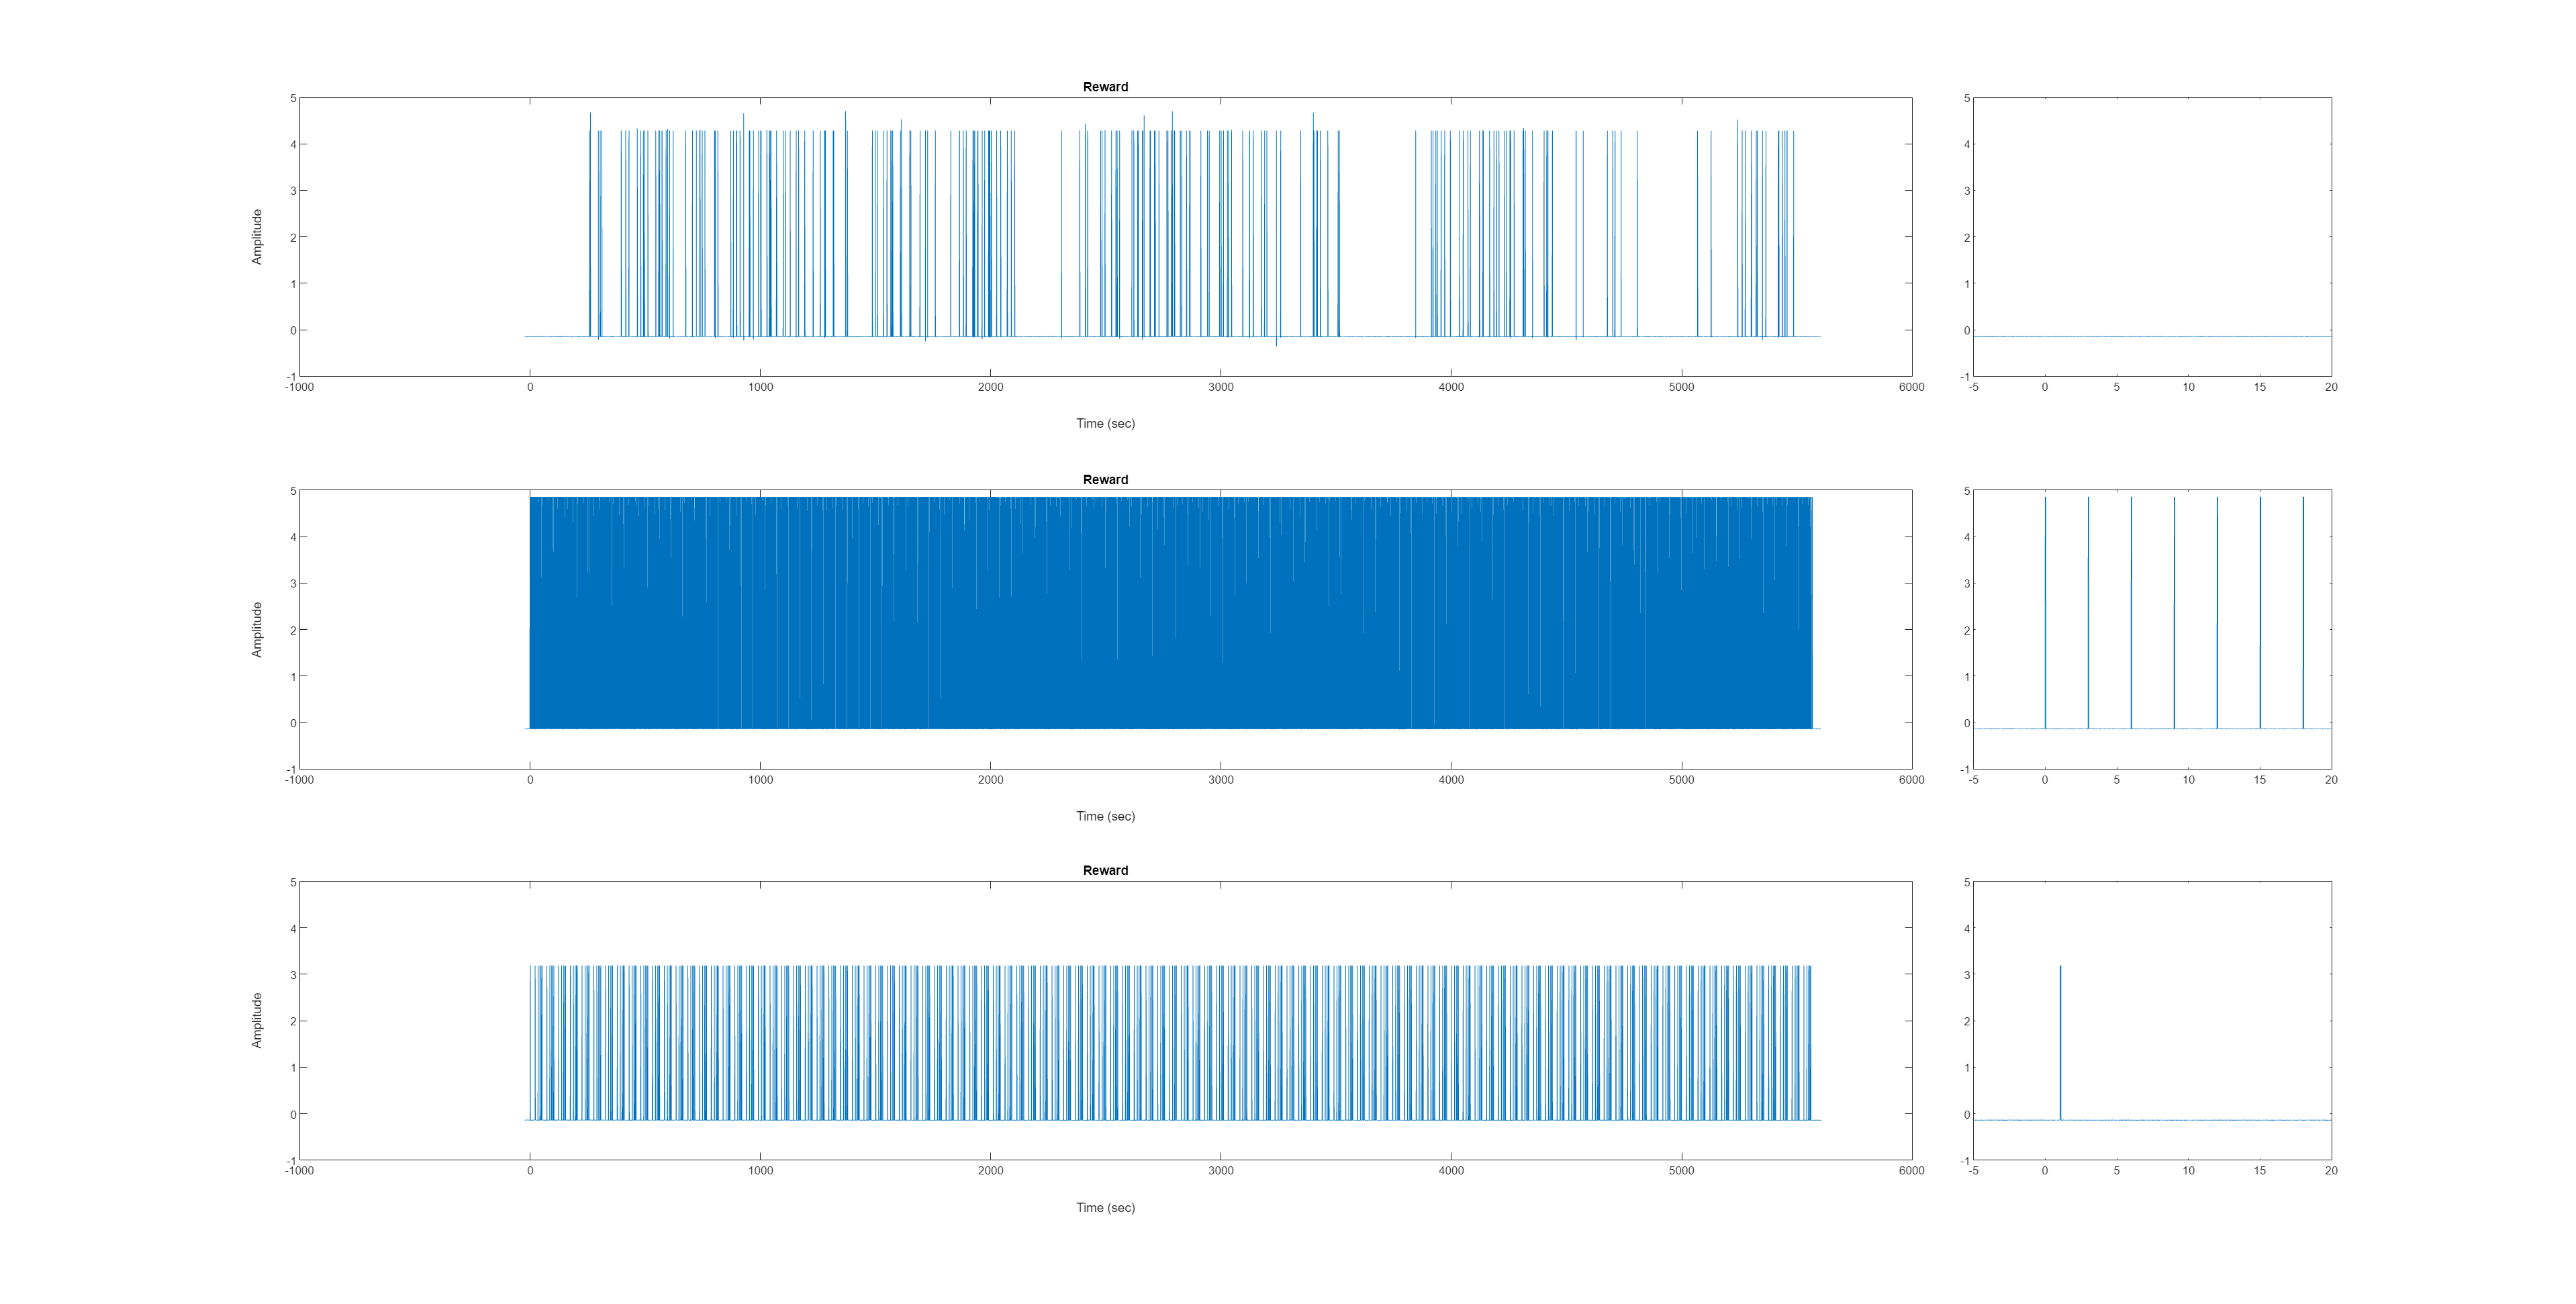

AnalogSignals = process_analog_signals(AnalogSignals,AnalogFrameRate);

save(fullfile(res_dir_path,'analog_signal.mat'),'AnalogSignals','AnalogFrameRate')

#### Aligning the reward signals to the global time

Reward data for each session have timestamps based on their local time, so they should be concatenated and assigned with the global timestamps. Also, add some columns to the output data.

[reward,reward_field] = concatenate_reward('reward');
% save(fullfile('analysis','extracted_reward.mat'),'reward','reward_field')
[reward,reward_field] = process_reward_data(reward,reward_field,reward_session,AnalogSignals);

Final MinPeakDistance was 1.0 
213 peaks were detected. 
All rewarding landings were recorded and detected.


save(fullfile('analysis','processed_reward.mat'),'reward','reward_field','reward_list','reward_session')

## Visualization

### Feeder/reward preference

Let's look at the feeder activation timings to see if the bats changed their feeder preference when the smoothie was switched.

First of all, check only one bat.

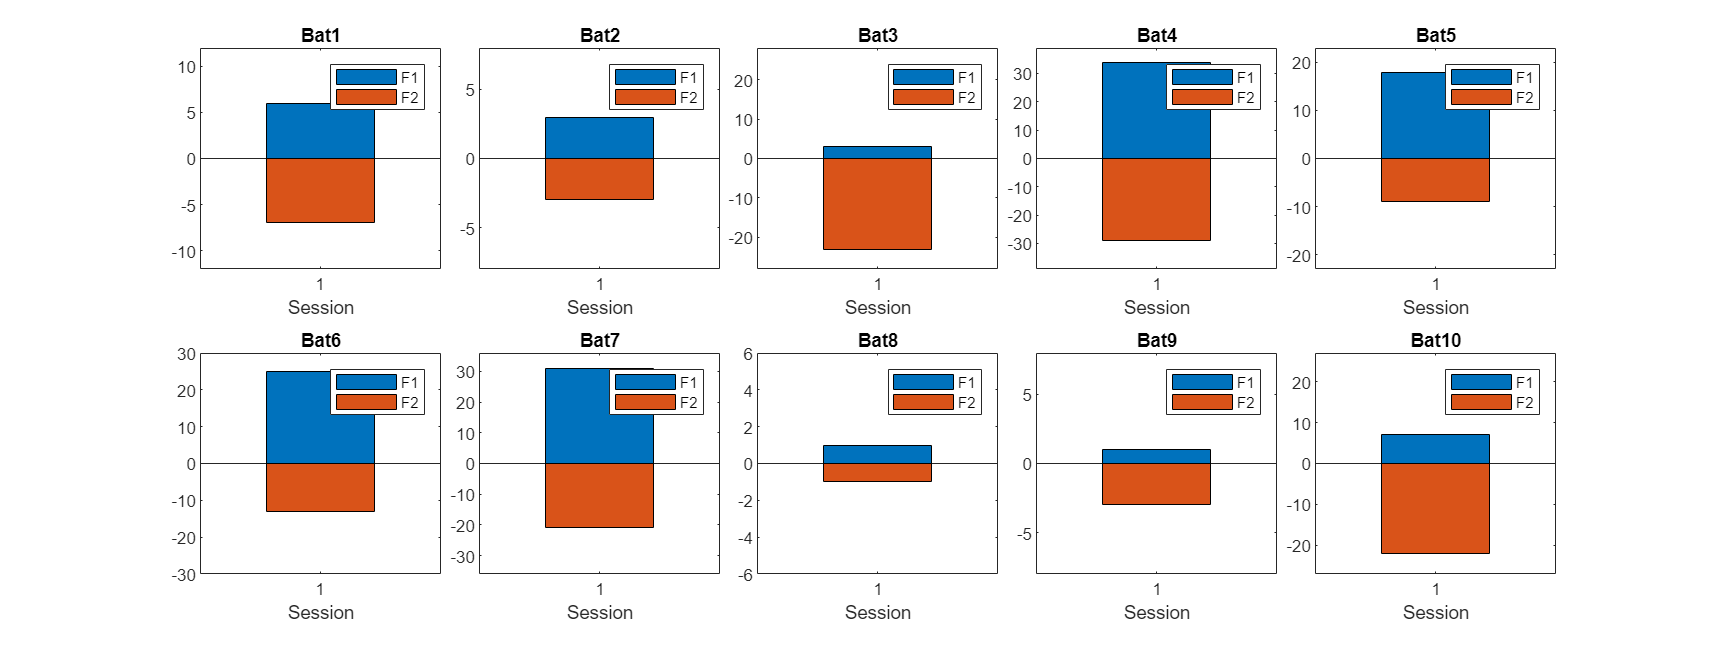

fig = figure;
fontsize(fig, 24, "points")
set(gcf, 'units','normalized','Position',[0.2 0.2 0.6 0.4]);
tiledlayout(2,5,"TileSpacing",'compact')
for bb = 1:n_tags
    feeder_pref = zeros(n_session,2);
    for ss = 1:n_session
        for ff = 1:2 % number of active feeder
            feeder_pref(ss,ff) = size(reward(reward(:,ismember(reward_field,{'bat_ID'}))==bb & reward(:,ismember(reward_field,{'session'}))==ss & reward(:,ismember(reward_field,{'activated_feeder'}))==ff,:),1);
        end
    end
    max_cnt = max(max(feeder_pref));
    feeder_pref(:,2) = feeder_pref(:,2)*-1;
    nexttile
    bar(categorical(1:n_session),feeder_pref,'stacked')
    title(sprintf('Bat%s',num2str(bb)))
    xlabel('Session')
    ylabel('')
    legend({"F1","F2"})
    ylim([-1*(max_cnt+5),max_cnt+5])
end

saveas(gcf,fullfile(fig_dir_path,'Feeder_preference.png'))

Also, the cumulative frequency of landings to each feeder is shown here:

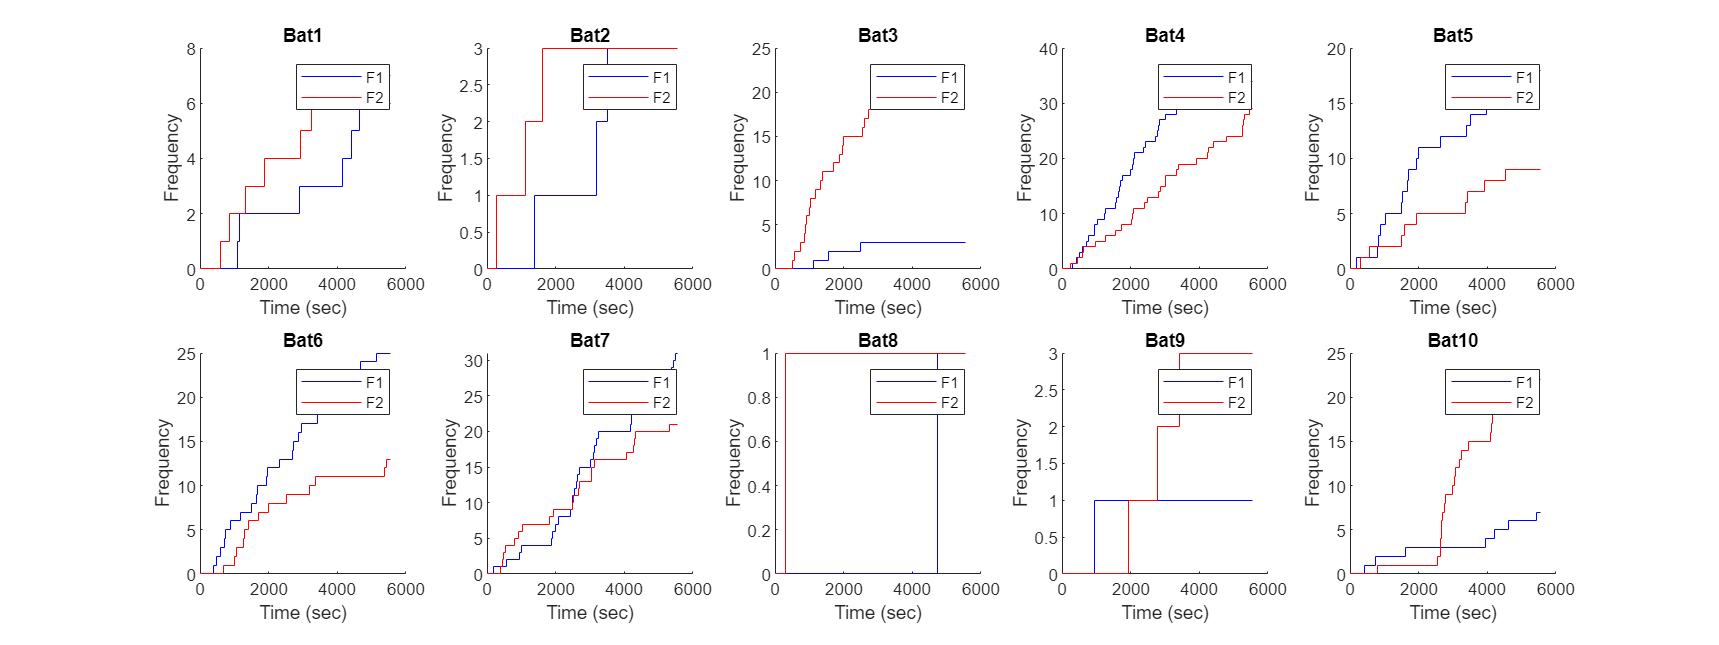

t_session = zeros(n_session,1);
for i=2:n_session
    t_session(i) = reward(find(reward(:,ismember(reward_field,'session'))==i,1,'first'),ismember(reward_field,'global_time'));
end

fig = figure;
fontsize(fig, 24, "points")
set(gcf, 'units','normalized','Position',[0.2 0.2 0.6 0.4]);
tiledlayout(2,5,"TileSpacing",'compact')
fig_clr = {'b','r'};
for bb = 1:n_tags
    nexttile
    hold on
    for ff = 1:2 % number of active feeder
        
        t_rw_cum = [];
        rw_cum = [];
        
        for ss = 1:n_session
            t_rw_cum = [t_rw_cum; t_session(ss)];
            rw_cum = [rw_cum; 0];
    
            t_rw_cum = [t_rw_cum; reward(reward(:,ismember(reward_field,'bat_ID'))==bb & ...
                reward(:,ismember(reward_field,'activated_feeder'))==ff & ...
                reward(:,ismember(reward_field,'session'))==ss,...
                ismember(reward_field,'global_time'))];
            rw_cum = [rw_cum;cumsum(ones(size(reward( ...
                reward(:,ismember(reward_field,'bat_ID'))==bb & ...
                reward(:,ismember(reward_field,'activated_feeder'))==ff & ...
                reward(:,ismember(reward_field,'session'))==ss,:),1),1))];
        end
        t_rw_cum = [t_rw_cum; t(end)];
        rw_cum = [rw_cum; rw_cum(end)];
    
        stairs(t_rw_cum,rw_cum,'Color',fig_clr{ff})
    end
    title(sprintf('Bat%s',num2str(bb)))
    xlabel('Time (sec)')
    ylabel('Frequency')
    
    y_lim = ylim;
    for ss = 2:n_session
        plot([t_session(ss),t_session(ss)],[y_lim(1),y_lim(2)+1],'k')
    end
    hold off

    f=get(gca,'Children');
    legend([f(length(f)),f(length(f)-1)],'F1','F2')
end

saveas(gcf,fullfile(fig_dir_path,'Cumulative_feeder_preference.png'))

The flaviors for the feeders were switched every session. Only the bat4 might have the feeder preference, but the others did not show flavior preferences.

### Detect landings based on the cdp data

#### Load data

load the extracted reward and behavior data.

load(fullfile(res_dir_path,'processed_reward.mat')) % reward
beh_dir         =   dir(fullfile(res_dir_path,'Ext_Behavior*','Extracted_Behavior*'));
load(fullfile(beh_dir.folder,beh_dir.name)) % behavior

#### Detect all landings on the feeders and non-feeder places

Extract the start/end timings and the position of all the landings. The extracted information is saved into `Landings`.

Landings   =   cell(n_tags,8); % Save the extracted behavior at the feeders
Landings_fields = cell(1,8); % field name of f

blanding = 1 - bflying; % Timing of landings

% Feeder coordinates
% r_fd = [2.77,0.82,1.75; 2.79,-0.99,1.64; 2.78,1.29,0.84; 2.78,-1.43,0.80]; % Feeder position
[r_fd,~] = r_feeder_calibrate('Y:\users\Tatsumi\Data\Flight_room_test\240120_feeder_calibration');

% Summarize the information for all the landings
for bb = 1:n_tags

    landing_start    =   find(diff([blanding(1,bb);blanding(:,bb)])==1); % The index of the variable t for the start of landings
    landing_end      =   find(diff([blanding(:,bb);blanding(end,bb)])==-1); % The index of the variable t for the end of landings

    % Omit the initial/last landing in some cases:
    if blanding(1,bb)~=1 % if the bat was flying when the recording started
        if blanding(end,bb)~=1 % if the bat was flying when the recording finished
        else % if the bat was landing when the recording finished
            landing_start(end) = [];
        end
    elseif blanding(1,bb)==1 % if the bat was landing when the recording started
        if blanding(end,bb)~=1 % if the bat was flying when the recording finished
            landing_end(1) = []; 
        else % if the bat was landing when the recording finished
            landing_start(end) = [];
            landing_end(1) = [];
        end
    end
    if length(landing_start) ~= length(landing_end)
        error('# of takeoff and landing mismatch. Check the detection.')
    else
        fprintf('%dth bat: %d landing was detected from the cdp data. \n',bb, length(landing_start))
    end

    n_land = length(landing_start); % Number of landings
    r_land = cell(n_land,1); % Position of all bats when a bat is landing
    r_land_median = zeros(n_land,3); % Median position of landings
    feeder_distance = zeros(n_land,4); % Distance to each feeder from landing spots
    closest_feeder = zeros(n_land,2); % Distance and identity evaluation of closest feeder at landing
    is_fd_land = false(n_land,1); % true if a landing on the feeders
    for ll = 1:n_land
        r_land{ll}   =   r(landing_start(ll):landing_end(ll),:,:);
        r_land_median(ll,:)   =   median(r_land{ll}(:,:,bb));
        for fd = 1:4
            feeder_distance(ll,fd) = vecnorm(r_fd(fd,:)-r_land_median(ll,:)); % Distance to each feeder
        end
        [min_dist, feeder_id] = min(feeder_distance(ll,:));
        closest_feeder(ll,1) = min_dist; % Distance to the closest feeder
        closest_feeder(ll,2) = feeder_id; % Identity of the closest feeder
        if min_dist < 0.2
            is_fd_land(ll) = true;
        end
    end
    

    % Save information into a variable
    Landings{bb,1} = t(landing_start);
    Landings{bb,2} = t(landing_end);
    Landings_fields{1} = 'land_start_t';
    Landings_fields{2} = 'land_end_t';    
    Landings{bb,3} = n_land;
    Landings_fields{3} = 'n_land';
    Landings{bb,4} = r_land;
    Landings{bb,5} = r_land_median;
    Landings_fields{4} = 'r_land';
    Landings_fields{5} = 'r_land_med';
    Landings{bb,6} = feeder_distance;
    Landings{bb,7} = closest_feeder;
    Landings{bb,8} = is_fd_land;
    Landings_fields{6} = 'fd_dist';
    Landings_fields{7} = 'fd_closest';
    Landings_fields{8} = 'is_fd_land';
end

1th bat: 67 landing was detected from the cdp data. 
2th bat: 24 landing was detected from the cdp data. 
3th bat: 102 landing was detected from the cdp data. 
4th bat: 94 landing was detected from the cdp data. 
5th bat: 118 landing was detected from the cdp data. 
6th bat: 182 landing was detected from the cdp data. 
7th bat: 92 landing was detected from the cdp data. 
8th bat: 13 landing was detected from the cdp data. 
9th bat: 27 landing was detected from the cdp data. 
10th bat: 65 landing was detected from the cdp data. 


The detected landings are validated visually by checking the bat's positions around the landing starts.

%% Visualize all landing
for bb = 1:n_tags

    t_land = Landings{bb,1};
    n_land = Landings{bb,3};
    is_fd_land = Landings{bb,8};

    range_draw = 20; % range to visualize around the feeder activation timing
    pre_t = 5; % time to draw before landing starts
    
    figure('Units','normalized','Position',[0.15,0.05,0.7,0.9],'Visible','off')
    tl = tiledlayout(5,5,"TileSpacing",'loose');
    title(tl,sprintf('Bat%d: %d sec after landings',bb,range_draw))
    fig_cnt = 1;
    save_cnt = 1;
    for ll = 1:n_land
        idx_t = find(ismember(round(t,2),round(t_land(ll),2)));
            if idx_t > 100*pre_t && idx_t < T - 100*range_draw
                r_plot = r(idx_t-100*pre_t:idx_t+100*range_draw,:,bb);
                t_plot = (-1*pre_t:0.01:range_draw)' + t(idx_t);
                l_plot = blanding(idx_t-100*pre_t:idx_t+100*range_draw,bb);
            elseif idx_t <= 100*pre_t
                r_plot = r(1:idx_t+100*range_draw,:,bb);
                t_plot = ((idx_t-1)/100:0.01:range_draw)' + t(idx_t);
                l_plot = blanding(1:idx_t+100*range_draw,bb);
            else
                r_plot = r(idx_t-100*pre_t:end,:,bb);
                t_plot = (-1*pre_t:0.01:(T-idx_t)/100)' + t(idx_t);
                l_plot = blanding(idx_t-100*pre_t:end,bb);
            end
        n = length(t_plot);
        cd = [uint8(jet(n)*255) uint8(ones(n,1))].';
    
        % t_plot = t(idx_feeder-100*60:idx_feeder+100*30);
    
        nexttile([1,4])
        hold on
        plot(t_plot,r_plot,'LineWidth',1);
        plot([t(idx_t),t(idx_t)],[-3,3],'k')
        area(t_plot,l_plot,'FaceAlpha',0.2,'LineStyle','none','FaceColor',[0.3010 0.7450 0.9330])
        hold off
        xlim([t(idx_t)-pre_t,t(idx_t)+range_draw])
        ylim([-3,3])
        if is_fd_land(ll)
            title(sprintf('%dth landing: feeder',ll))
        else
            title(sprintf('%dth landing: non-feeder',ll))
        end
        xlabel('Time (sec)')
        ylabel('Position (m)')
        legend({'x','y','z','Beam blocked'})
    
        nexttile([1,1])
        hold on
        p = plot(r_plot(:,1),r_plot(:,2));
        drawnow
        set(p.Edge, 'ColorBinding','interpolated', 'ColorData',cd)
        scatter(r(idx_t,1,bb),r(idx_t,2,bb),20,'k','filled')

        rectangle('Position',[r_fd(1,1)-0.1,r_fd(1,2)-0.1,0.2,0.2],'EdgeColor','k')
        rectangle('Position',[r_fd(2,1)-0.1,r_fd(2,2)-0.1,0.2,0.2],'EdgeColor','k')
        rectangle('Position',[r_fd(3,1)-0.1,r_fd(3,2)-0.1,0.2,0.2],'EdgeColor','c')
        rectangle('Position',[r_fd(4,1)-0.1,r_fd(4,2)-0.1,0.2,0.2],'EdgeColor','c')
        hold off
        title('Top view')
        xlabel('x (m)')
        ylabel('y (m)')
        xlim([r_lim(1,1),r_lim(1,2)])
        ylim([r_lim(2,1),r_lim(2,2)])
    
        % nexttile([1,1])
        % hold on
        % p = plot(r_plot(:,2),r_plot(:,3));
        % drawnow
        % set(p.Edge, 'ColorBinding','interpolated', 'ColorData',cd)
        % scatter(r(idx_feeder,2,bb),r(idx_feeder,3,bb),20,'k','filled')
        % hold off
        % xlabel('y')
        % ylabel('z')
        % xlim([r_lim(2,1),r_lim(2,2)])
        % ylim([r_lim(3,1),r_lim(3,2)])
    
        if fig_cnt < 5
            fig_cnt = fig_cnt + 1;
        else
            if ll ~= n_land
                saveas(gcf,fullfile(res_dir_path,'figure',['AllLandings_bat' num2str(bb) '_' num2str(save_cnt) '.png']));
                save_cnt = save_cnt + 1;
                close all

                figure('Units','normalized','Position',[0.15,0.05,0.7,0.9],'Visible','off')
                tl = tiledlayout(5,5,"TileSpacing",'loose');
                title(tl,sprintf('Bat%s',num2str(bb)))
                fig_cnt = 1;
            end
        end
    end

    saveas(gcf,fullfile(res_dir_path,'figure',['AllLandings_bat' num2str(bb) '_' num2str(save_cnt) '.png']));
    close all
end

#### Landings on only the feeders

Landings_fd   =   cell(n_tags,7); % Save the extracted behavior at the feeders
Landings_fd_fields = Landings_fields(1:7); % field name of Landings_fd

for bb = 1:n_tags
    is_fd_land = Landings{bb,8};
    n_fd_land = sum(is_fd_land); % number of landings on feeders
    
    Landings_fd{bb,1} = Landings{bb,1}(is_fd_land,:);
    Landings_fd{bb,2} = Landings{bb,2}(is_fd_land,:);
    Landings_fd{bb,3} = n_fd_land;
    Landings_fd{bb,4} = Landings{bb,4}(is_fd_land,:);
    Landings_fd{bb,5} = Landings{bb,5}(is_fd_land,:);
    Landings_fd{bb,6} = Landings{bb,6}(is_fd_land,:);
    Landings_fd{bb,7} = Landings{bb,7}(is_fd_land,:);
end

%% Visualize all landing
for bb = 1:n_tags

    t_land = Landings_fd{bb,1};
    n_land = Landings_fd{bb,3};

    range_draw = 20; % range to visualize around the feeder activation timing
    pre_t = 5; % time to draw before landing starts
    
    figure('Units','normalized','Position',[0.15,0.05,0.7,0.9],'Visible','off')
    tl = tiledlayout(5,5,"TileSpacing",'loose');
    title(tl,sprintf('Bat%d: %d sec after landings',bb,range_draw))
    fig_cnt = 1;
    save_cnt = 1;
    for ll = 1:n_land
        idx_t = find(ismember(round(t,2),round(t_land(ll),2)));
            if idx_t > 100*pre_t && idx_t < T - 100*range_draw
                r_plot = r(idx_t-100*pre_t:idx_t+100*range_draw,:,bb);
                t_plot = (-1*pre_t:0.01:range_draw)' + t(idx_t);
                l_plot = blanding(idx_t-100*pre_t:idx_t+100*range_draw,bb);
            elseif idx_t <= 100*pre_t
                r_plot = r(1:idx_t+100*range_draw,:,bb);
                t_plot = ((idx_t-1)/100:0.01:range_draw)' + t(idx_t);
                l_plot = blanding(1:idx_t+100*range_draw,bb);
            else
                r_plot = r(idx_t-100*pre_t:end,:,bb);
                t_plot = (-1*pre_t:0.01:(T-idx_t)/100)' + t(idx_t);
                l_plot = blanding(idx_t-100*pre_t:end,bb);
            end
        n = length(t_plot);
        cd = [uint8(jet(n)*255) uint8(ones(n,1))].';
    
        % t_plot = t(idx_feeder-100*60:idx_feeder+100*30);
    
        nexttile([1,4])
        hold on
        plot(t_plot,r_plot,'LineWidth',1);
        plot([t(idx_t),t(idx_t)],[-3,3],'k')
        area(t_plot,l_plot,'FaceAlpha',0.2,'LineStyle','none','FaceColor',[0.3010 0.7450 0.9330])
        hold off
        xlim([t(idx_t)-pre_t,t(idx_t)+range_draw])
        ylim([-3,3])
        title(sprintf('%dth landing: feeder',ll))
        xlabel('Time (sec)')
        ylabel('Position (m)')
        legend({'x','y','z','Beam blocked'})
    
        nexttile([1,1])
        hold on
        p = plot(r_plot(:,1),r_plot(:,2));
        drawnow
        set(p.Edge, 'ColorBinding','interpolated', 'ColorData',cd)
        scatter(r(idx_t,1,bb),r(idx_t,2,bb),20,'k','filled')

        rectangle('Position',[r_fd(1,1)-0.1,r_fd(1,2)-0.1,0.2,0.2],'EdgeColor','k')
        rectangle('Position',[r_fd(2,1)-0.1,r_fd(2,2)-0.1,0.2,0.2],'EdgeColor','k')
        rectangle('Position',[r_fd(3,1)-0.1,r_fd(3,2)-0.1,0.2,0.2],'EdgeColor','c')
        rectangle('Position',[r_fd(4,1)-0.1,r_fd(4,2)-0.1,0.2,0.2],'EdgeColor','c')
        hold off
        title('Top view')
        xlabel('x (m)')
        ylabel('y (m)')
        xlim([r_lim(1,1),r_lim(1,2)])
        ylim([r_lim(2,1),r_lim(2,2)])
    
        % nexttile([1,1])
        % hold on
        % p = plot(r_plot(:,2),r_plot(:,3));
        % drawnow
        % set(p.Edge, 'ColorBinding','interpolated', 'ColorData',cd)
        % scatter(r(idx_feeder,2,bb),r(idx_feeder,3,bb),20,'k','filled')
        % hold off
        % xlabel('y')
        % ylabel('z')
        % xlim([r_lim(2,1),r_lim(2,2)])
        % ylim([r_lim(3,1),r_lim(3,2)])
    
        if fig_cnt < 5
            fig_cnt = fig_cnt + 1;
        else
            if ll ~= n_land
                saveas(gcf,fullfile(res_dir_path,'figure',['FeederLandings_bat' num2str(bb) '_' num2str(save_cnt) '.png']));
                save_cnt = save_cnt + 1;
                close all

                figure('Units','normalized','Position',[0.15,0.05,0.7,0.9],'Visible','off')
                tl = tiledlayout(5,5,"TileSpacing",'loose');
                title(tl,sprintf('Bat%d: %d sec after landings',bb,range_draw))
                fig_cnt = 1;
            end
        end
    end

    saveas(gcf,fullfile(res_dir_path,'figure',['FeederLandings_bat' num2str(bb) '_' num2str(save_cnt) '.png']));
    close all
end

Compare the number of detected landings between the cdp and the reward delivery data.

th_d_fd = 0.2; % threshold of the distance from feeders
for bb = 1:n_tags
    r_land_med = Landings_fd{bb,5};
    n_land = Landings_fd{bb,3};
    
    is_land_f1 = Landings_fd{bb,7}(:,2)==1;
    is_land_f2 = Landings_fd{bb,7}(:,2)==2;
    d_land_f1 = Landings_fd{bb,7}(is_land_f1,1);
    d_land_f2 = Landings_fd{bb,7}(is_land_f2,1);
    is_land_anyf = any([is_land_f1,is_land_f2],2);
    fprintf('Bat%d landings on feeder: cdp %d, analog %d\n',bb,sum(is_land_anyf),sum(reward(:,9)==bb))
end

Bat1 landings on feeder: cdp 14, analog 13
Bat2 landings on feeder: cdp 4, analog 6
Bat3 landings on feeder: cdp 23, analog 26
Bat4 landings on feeder: cdp 63, analog 63
Bat5 landings on feeder: cdp 32, analog 27
Bat6 landings on feeder: cdp 77, analog 38
Bat7 landings on feeder: cdp 52, analog 52
Bat8 landings on feeder: cdp 1, analog 2
Bat9 landings on feeder: cdp 0, analog 4
Bat10 landings on feeder: cdp 25, analog 32


#### Time fraction of social rewarding on the feeders

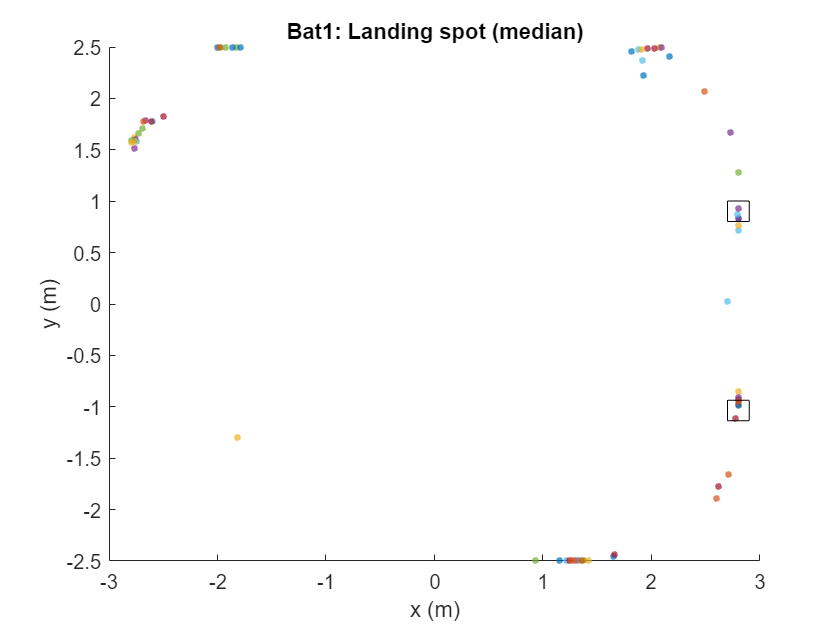

Bat1 landings on feeder: cdp 14, analog 13
Bat2 landings on feeder: cdp 4, analog 6
Bat3 landings on feeder: cdp 23, analog 26
Bat4 landings on feeder: cdp 63, analog 63
Bat5 landings on feeder: cdp 32, analog 27
Bat6 landings on feeder: cdp 77, analog 38
Bat7 landings on feeder: cdp 52, analog 52
Bat8 landings on feeder: cdp 1, analog 2
Bat9 landings on feeder: cdp 0, analog 4
Bat10 landings on feeder: cdp 25, analog 32


Bat1 landings on feeder: cdp 25, analog 0
Bat2 landings on feeder: cdp 25, analog 0
Bat3 landings on feeder: cdp 25, analog 0
Bat4 landings on feeder: cdp 25, analog 0
Bat5 landings on feeder: cdp 25, analog 0
Bat6 landings on feeder: cdp 25, analog 0
Bat7 landings on feeder: cdp 25, analog 0
Bat8 landings on feeder: cdp 25, analog 0
Bat9 landings on feeder: cdp 25, analog 0
Bat10 landings on feeder: cdp 25, analog 0


% Door view
figure('Units','normalized','Position',[0.05,0.2,0.7,0.4])

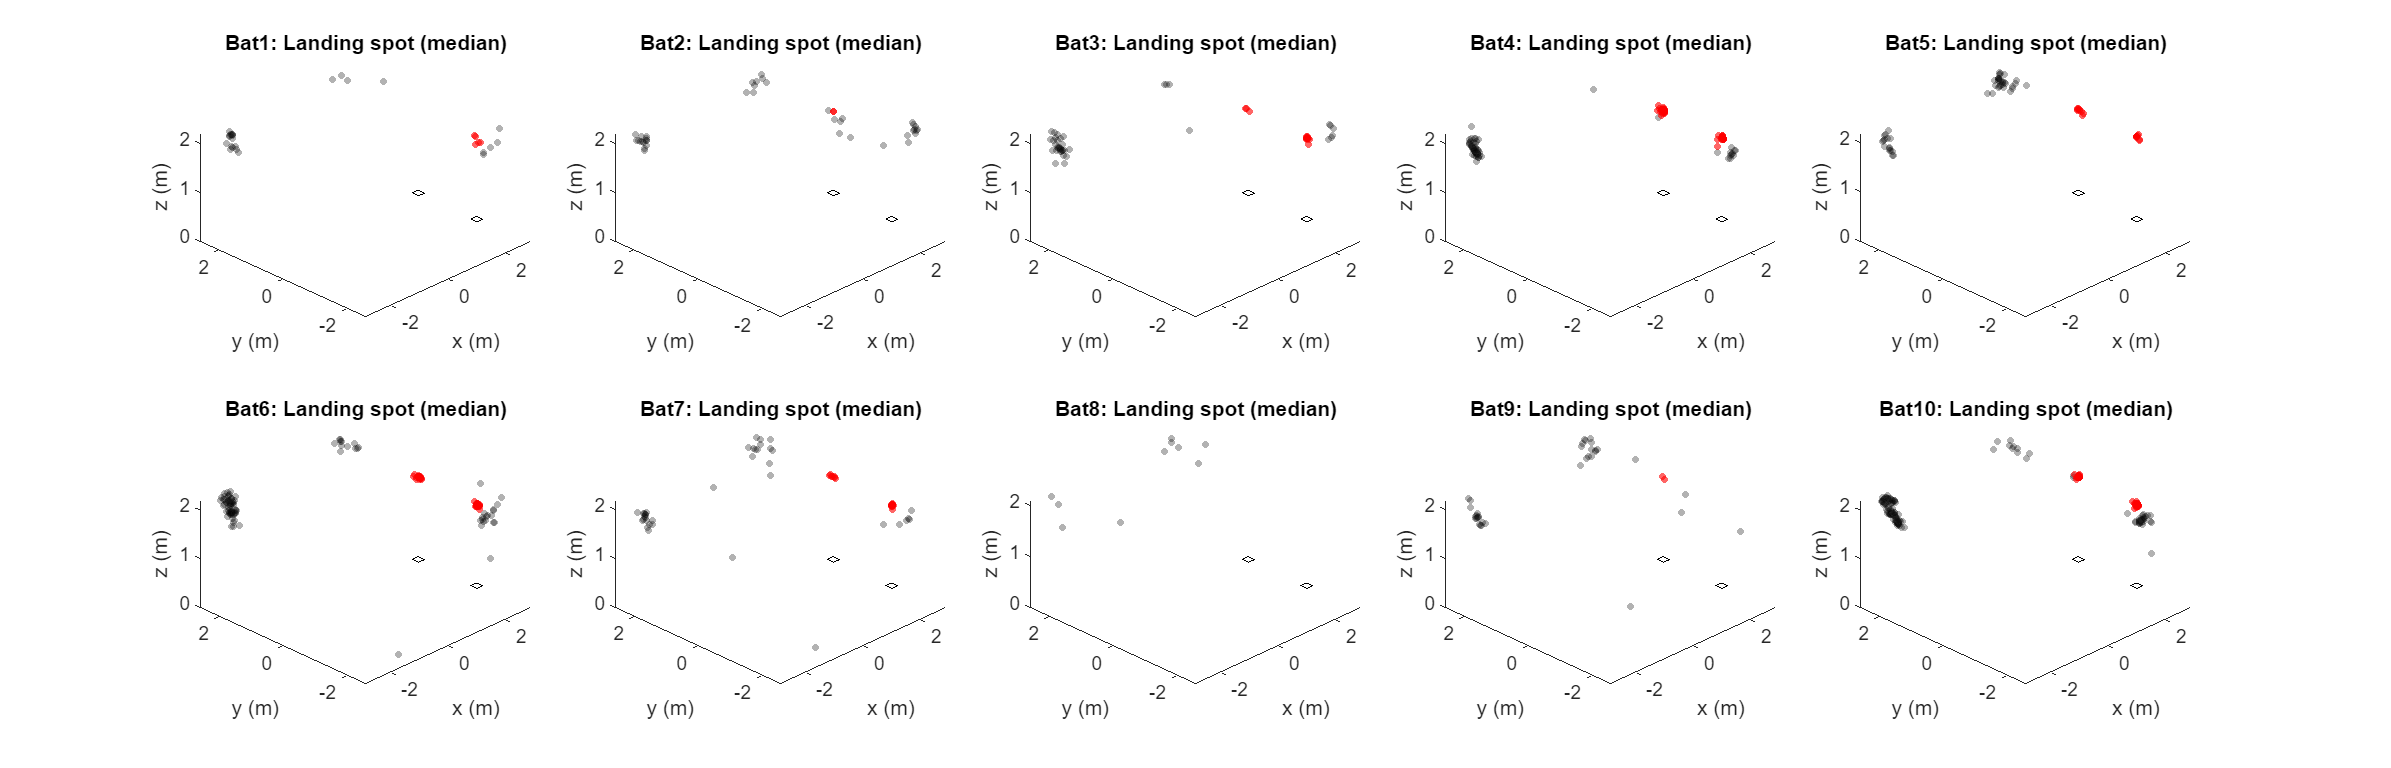

tl = tiledlayout(2,5,"TileSpacing",'loose');
for bb = 1:n_tags
    r_land_med = Landings{bb,5};
    n_land = length(r_land_med);
    is_land_anyf = Landings{bb,13};
    % figure
    nexttile
    hold on
    for ll = 1:n_land
        if is_land_anyf(ll)
            scatter3(r_land_med{ll}(1),r_land_med{ll}(2),r_land_med{ll}(3),100,'.r','MarkerEdgeAlpha',0.6)
        else
            scatter3(r_land_med{ll}(1),r_land_med{ll}(2),r_land_med{ll}(3),100,'.k','MarkerEdgeAlpha',0.3)
        end
        view([-45,45])
    end
    rectangle('Position',[r_fd(1,1)-0.1,r_fd(1,2)-0.1,0.2,0.2],'EdgeColor','k')
    rectangle('Position',[r_fd(2,1)-0.1,r_fd(2,2)-0.1,0.2,0.2],'EdgeColor','k')
    hold off
    xlabel('x (m)')
    ylabel('y (m)')
    zlabel('z (m)')
    xlim([r_lim(1,1),r_lim(1,2)])
    ylim([r_lim(2,1),r_lim(2,2)])
    title(sprintf('Bat%s: Landing spot (median)',num2str(bb)))
end
saveas(gcf,fullfile(res_dir_path,'figure','landing_spot_allbat_door_view.png'));
% Top view

figure('Units','normalized','Position',[0.05,0.2,0.7,0.4])
tl = tiledlayout(2,5,"TileSpacing",'loose');
% title(tl,sprintf('Bat%s',num2str(bb)))
for bb = 1:n_tags
    r_land_med = Landings{bb,5};
    n_land = length(r_land_med);
    is_land_anyf = Landings{bb,13};
    % figure
    nexttile
    hold on
    for ll = 1:n_land
        if is_land_anyf(ll)
            scatter3(r_land_med{ll}(1),r_land_med{ll}(2),r_land_med{ll}(3),100,'.r','MarkerEdgeAlpha',0.6)
        else
            scatter3(r_land_med{ll}(1),r_land_med{ll}(2),r_land_med{ll}(3),100,'.k','MarkerEdgeAlpha',0.3)
        end
        view([0,90])
    end
    rectangle('Position',[r_fd(1,1)-0.1,r_fd(1,2)-0.1,0.2,0.2],'EdgeColor','k')
    rectangle('Position',[r_fd(2,1)-0.1,r_fd(2,2)-0.1,0.2,0.2],'EdgeColor','k')
    hold off
    xlabel('x (m)')
    ylabel('y (m)')
    zlabel('z (m)')
    xlim([r_lim(1,1),r_lim(1,2)])
    ylim([r_lim(2,1),r_lim(2,2)])
    title(sprintf('Bat%s: Landing spot (median)',num2str(bb)))
end
saveas(gcf,fullfile(res_dir_path,'figure','landing_spot_allbat_top_view.png'));

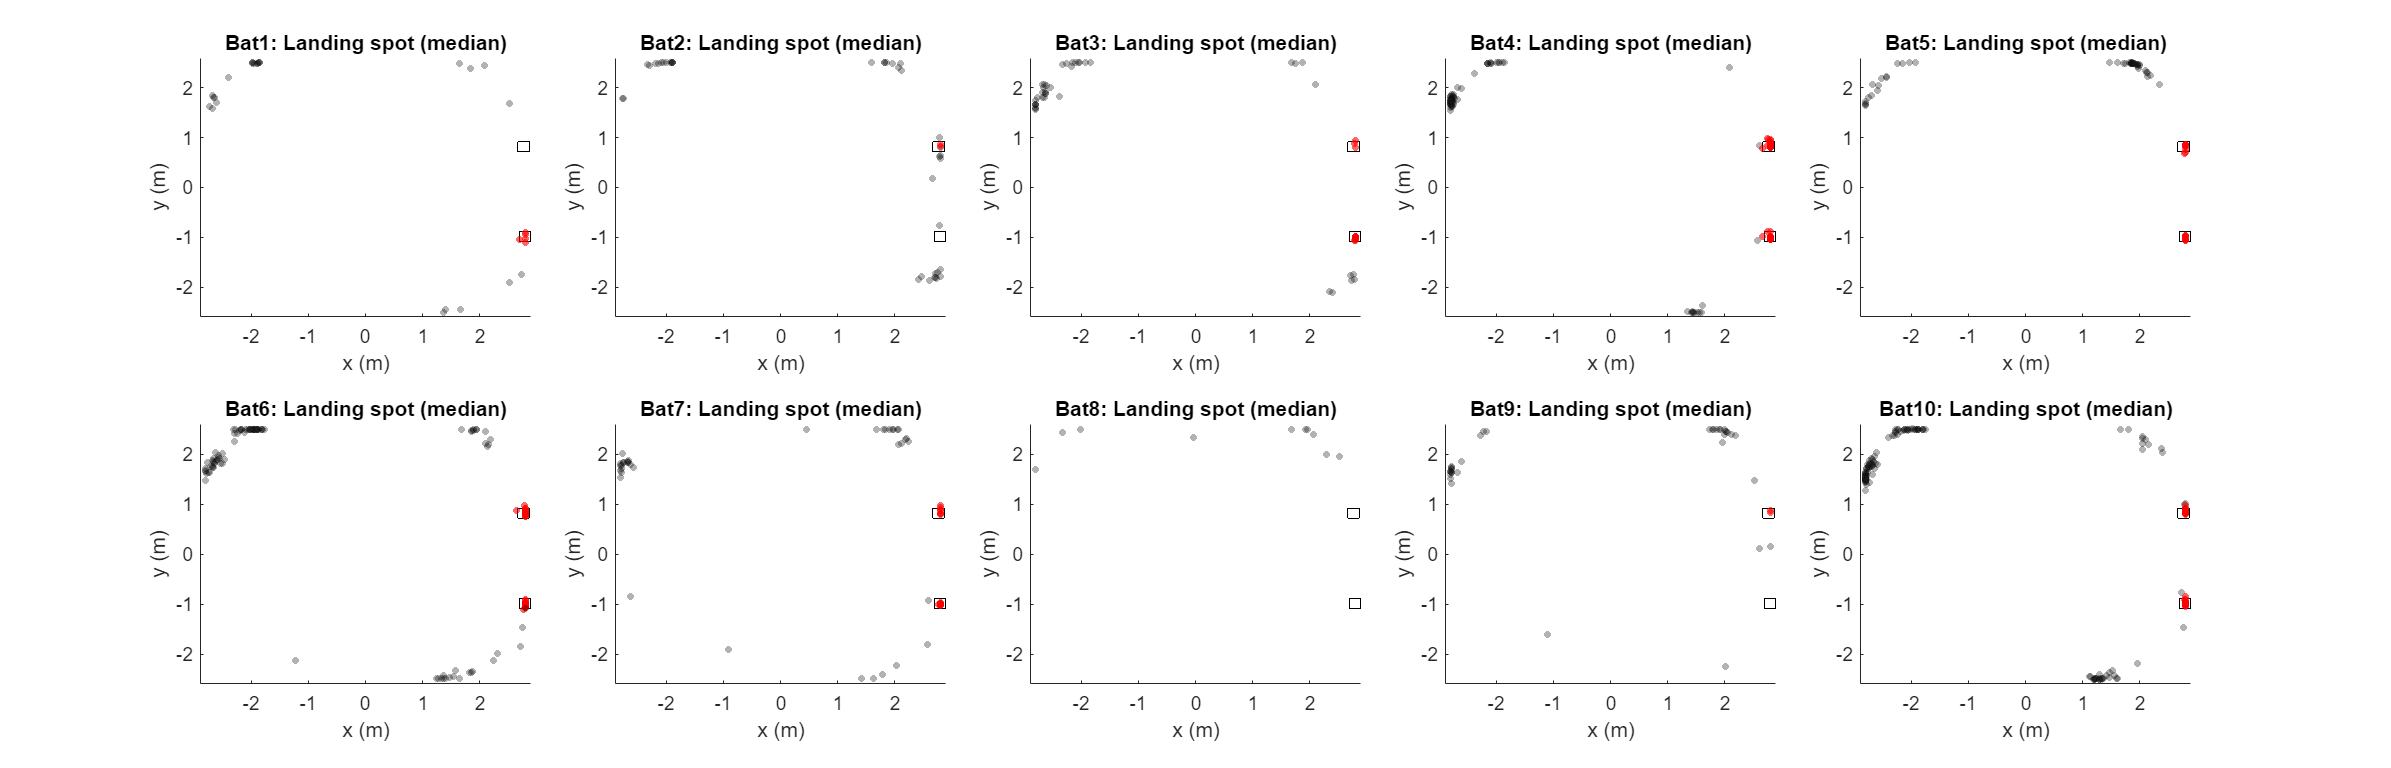

% Distance to others when landed on any feeder

d_oth_all = [];
d_oth_min_all = [];

for bb = 1:n_tags
    
    is_land_anyf = Landings{bb,13};
    n_land_fd = sum(is_land_anyf);
    t_land_fd = Landings{bb,1}(is_land_anyf);
    t_land_fd = find(ismember(round(t,2),round(t_land_fd,2)));
    r_land = Landings{bb,4}(is_land_anyf);
    
    d_oth = zeros(n_land_fd,n_tags-1);
    for ll = 1:n_land_fd
        r_land_self = r_land{ll}(1,:,1);
        r_oth = squeeze(r_land{ll}(1,:,[1:bb-1,bb+1:end]));
    
        for oth = 1:n_tags-1
            d_oth(ll,oth) = norm(r_oth(:,oth)-r_land_self);
        end
    end
    d_oth_min = min(d_oth,[],2);
    d_oth_min_all = [d_oth_min_all;[d_oth_min,repmat(bb,[length(d_oth_min),1])]];

    d_oth_all = [d_oth_all;[d_oth, repmat(bb,size(d_oth,1),1)]];

end


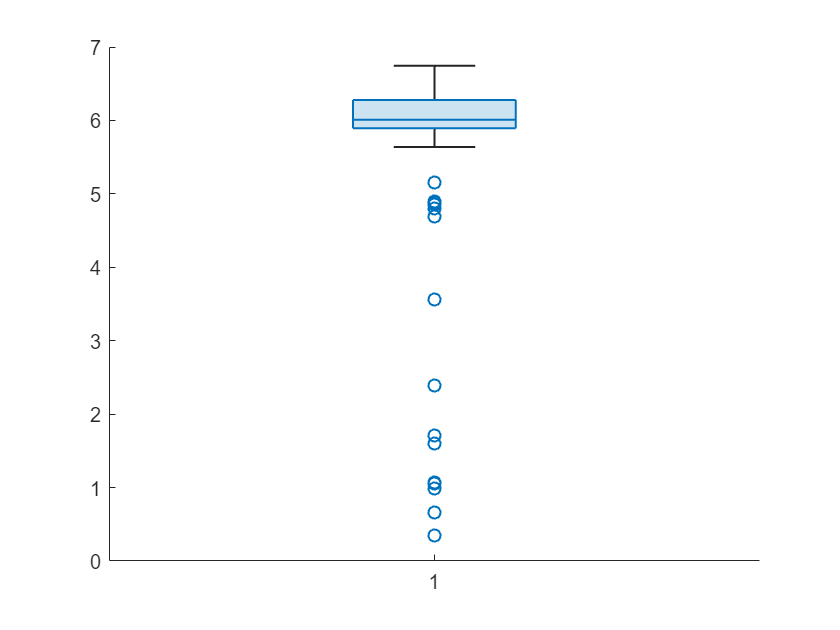

figure
boxchart(d_oth_min_all(:,1))

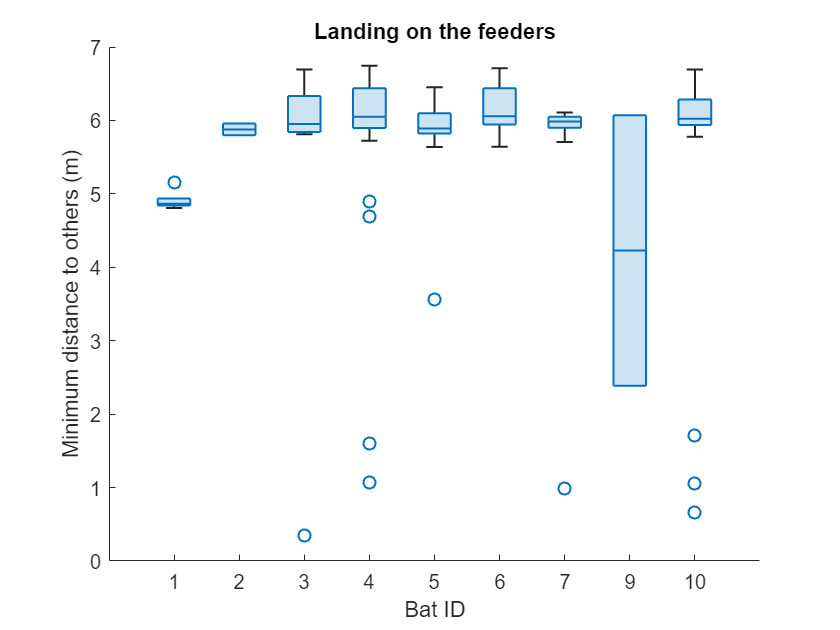

figure
boxchart(categorical(d_oth_min_all(:,2)),d_oth_min_all(:,1))
xlabel('Bat ID')
ylabel('Minimum distance to others (m)')
title('Landing on the feeders')

saveas(gcf,fullfile(res_dir_path,'figure','min_dist_others.png'));

figure('Units','normalized','Position',[0.05,0.2,0.7,0.4])
tl = tiledlayout(2,5,"TileSpacing",'loose');

for bb = 1:n_tags
    nexttile
    boxchart(categorical(d_oth_all(:,2)),d_oth_min_all(:,1))



%% Detect all landings




% % Check if the feeders are activated while the bats land
% figure();   set(gcf, 'units','normalized','outerposition',[0 0 1 1]);
% tiledlayout(n_tags,1,"TileSpacing",'tight')
% 
% for bb = 1:n_tags
%     ax(bb) = nexttile;
%     area(t,bflying(:,bb)*5,'FaceAlpha',0.5,'LineStyle','none'); 
%     hold on
%     % area(t,ismember(round(t,2),round(f{bb,strcmp(f_fields,'b_feeder_t')},2))*3,'FaceAlpha',0.7,'LineStyle','none','FaceColor','r')
%     plot(t,r(:,1,bb))
%     scatter(round(f{bb,strcmp(f_fields,'b_feeder_t')},2),5*ones(length(f{bb,strcmp(f_fields,'b_feeder_t')}),1),10,'k')
%     hold off
%     legend({'Fly','x','feeder'})
% end
% xlabel('Tiem (sec)')
% linkaxes(ax)
% 
% % Coordinate of position when the feeders were activated
% figure();   set(gcf, 'units','normalized','outerposition',[0 0.3 1 0.5]);
% tiledlayout(1,3,"TileSpacing",'tight')
% 
% for bb = 1:n_tags
%     r_med_feed = f{bb,10};
% 
%     nexttile(1); hold on
%     for ll = 1:size(r_med_feed,1)
%         scatter(r_med_feed{ll}(1),r_med_feed{ll}(2)) % XY
%     end
%     hold off
%     xlim(r_lim(1,:))
%     ylim(r_lim(2,:))
%     xlabel('x')
%     ylabel('y')
% 
%     nexttile(2); hold on
%     for ll = 1:size(r_med_feed,1)
%         scatter(r_med_feed{ll}(1),r_med_feed{ll}(3)) % XZ
%     end
%     hold off
%     xlim(r_lim(1,:))
%     ylim(r_lim(3,:))
%     xlabel('x')
%     ylabel('z')
% 
%     nexttile(3); hold on
%     for ll = 1:size(r_med_feed,1)
%         scatter(r_med_feed{ll}(2),r_med_feed{ll}(3)) % YZ
%     end
%     hold off
%     xlim(r_lim(2,:))
%     ylim(r_lim(3,:))
%     xlabel('y')
%     ylabel('z')
% 
%     pause(3)
% end

% %% Correct feeder positions (s)
% r_fd = [2.77,0.82,1.75; 2.79,-0.99,1.64; 2.78,1.29,0.84; 2.78,-1.43,0.80]; % Feeder position
% 
% %=== Correct feeder position(s) 
% if Group_name == 'D'
%     [~,fd_idx] = min(vecnorm(r_fd-centroid_all,2,2));
%     r_fd(1,:) = centroid_all(fd_idx,:);                                                  
% else
%     for i=1:4
%     [feeder_distance,fd_idx] = min(vecnorm(r_fd(i,:)-centroid_all,2,2));
%     if feeder_distance<0.2,r_fd(i,:) =  centroid_all(fd_idx,:);end  % Do not correct if further than 20 cm
%     end
% end

